### **Projeto 2 - Tópicos em Engenharia Mecatronica**

**Nome: Gabriel Evangelista Correia**

**RA: 250320**

**Parte 0**

clc;
clear;
close all force;

load input.mat
RA = '250320';
[L, B, a, w0, E] = dados_de_entrada(RA, T);
fprintf('L: %.4f\n', L)

L: 7.9000


fprintf('B: %.4f\n', B)

B: 0.1940


fprintf('a: %.4f\n', a)

a: 0.4620


fprintf('w0: %.4f\n', w0)

w0: 88200.0000


fprintf('E: %.4f\n', E)

E: 192700000000.0000


Nessa parte do projeto, foi criado uma funçao que recebe como parametros o meu RA e a tabela T fornecida. Nessa funcao procurei na primeira coluna a string correspondente ao meu RA. Depois disso, consegui encontrar nessa linha os valores correpondentes a L, B, a, w0, E, pedidos para realizaçao dos proximos passos.

**Parte 1** 

    % Area da seção transversal
    A = integral(@(z) a*cos(pi*z/B), -B/2, B/2);
    fprintf('Área da seção transversal: %.4f\n', A)

Área da seção transversal: 0.0571



    % Primeiro momento de área
    Qz = (a^2/2) * integral(@(z) cos(pi*z/B).^2, -B/2, B/2);
    fprintf('Primeiro Momento de area: %.4f\n', Qz)

Primeiro Momento de area: 0.0104


    % Primeiro momento de área com integral dupla
    Qz_integral2 = integral2(@(z, y) y, -B/2, B/2, 0,  @(z) a*cos(pi*z/B));
    fprintf('Primeiro Momento de area com integral dupla: %.4f\n', Qz_integral2)

Primeiro Momento de area com integral dupla: 0.0104


    
    % Localização do centroide
    Yc = Qz / A;
    fprintf('Centroide: %.4f\n', Yc)

Centroide: 0.1814


    % Centroide esperado
    Yc_esperado = pi*a/8;
    fprintf('Centroide esperado: %.4f\n', Yc_esperado)

Centroide esperado: 0.1814



    % Segundo momento de área com integral simples e teorema dos eixos paralelos
    Izz = (a^3/3) * integral(@(z) cos(pi*z/B).^3, -B/2, B/2) - A*(Yc^2);
    fprintf('Segundo momento de area com integracao simples : %.5f\n', Izz)

Segundo momento de area com integracao simples : 0.00083


    % Segundo momento de área com integral dupla
    Izz_integral2 = integral2(@(z, y) y.^2, -B/2, B/2, -Yc, @(z) a*cos(pi*z/B)-Yc);
    fprintf('Segundo momento de area com integracao dupla : %.5f\n', Izz_integral2)

Segundo momento de area com integracao dupla : 0.00083


    % Segundo momento de área esperado
    Izz_esperado = ((128-9*pi^2)*B*a^3) / (288*pi);
    fprintf('Segundo momento de area esperado : %.5f\n', Izz_esperado)

Segundo momento de area esperado : 0.00083



    % Erro relativo
    erro_relativo = abs(Izz_esperado-Izz)/Izz_esperado

erro_relativo = 3.9269e-16

A integraçao numérica foi realizada atravez da funçao integral do Matlab uma vez que a funçao e os limites de integraçao sao conhecidos. No caso do exercicio proposto, a integral dupla fornece resultados mais precisos do que a integral simples, apesar de mais complexa de ser implementada, uma vez que considera a integraçao sobre duas variaveis. Na integracao simples assume-se uma constante em um dos eixos.

Podemos observar pelo calculo do erro relativo que ha erros nos calculos se comparados com os valores analiticos esperados. Porem, esse erro é tao pequeno que pode ser desprezado e aceitado dentro da resolucao do problema, de forma que nao se necessita de um tratamento.

**Parte 2**

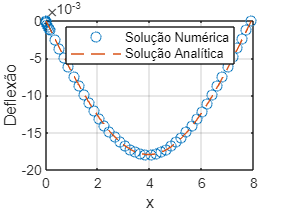


Mz_calculo_numerico = @(x) (-w0/(3*L)).*x.^3 + (2*w0/(3*L)).*sing(x - L/2, 3) + w0*L*x/4;
Vy_calculo_analitico = @(x) ((-w0/(60*L)).*x.^5 + (w0/(30*L)).*sing(x - L/2, 5) + (w0*L.*x.^3)./24 - (5*w0*L^3.*x)./192)./(E*Izz_esperado); 
A = @(x, u)[u(2); Mz_calculo_numerico(x)./(E*Izz)];
u0 = [0 -7.08*10^-3];
dt = [0 L]; 
[x, u] = ode45(A, dt, u0);
Vy_calculo_numerico = u(:,1);
dy = u(:,1);

plot(x, Vy_calculo_numerico, 'o', x, Vy_calculo_analitico(x), '--')
xlabel('x');
ylabel('Deflexão');
legend('Solução Numérica', 'Solução Analítica', 'location', 'best');
grid on;

A equaçao de segunda ordem foi reduzida para uma de primeira fazendo theta = y (inclinaçao). O integrador do Matlab utilizado para determinar Vy foi o ode45, pois foi o que se mostrou mais eficaz no calculo. O metodo utilizado na escolha de um theta apropriado para o metodo de shooting foi apenas a analise do grafico plotado e chute de valores ate que as curvas ficassem plenamente ajustadas.

Para encontrar a solucao do problema de valor de contorno foi necessario determinar a inclinaçao necessaria.

function [L, B, a, w0, E] = dados_de_entrada(RA, T)
    
    % Buscando meu RA na primeira coluna da tabela 
    linha = find(strcmp(T.RA, RA));
    % Pegando os parametros pedidos no exercicio da tabela dada
    L = T.L(linha);
    B = T.B(linha);
    a = T.a(linha);
    w0 = T.w0(linha);
    E = T.E(linha);

end

function y = sing(x,n) 
    
    if n>=0 
        y = x.^n.*(x>=0); 
    else 
        y = 0*x; 
    end 
end
